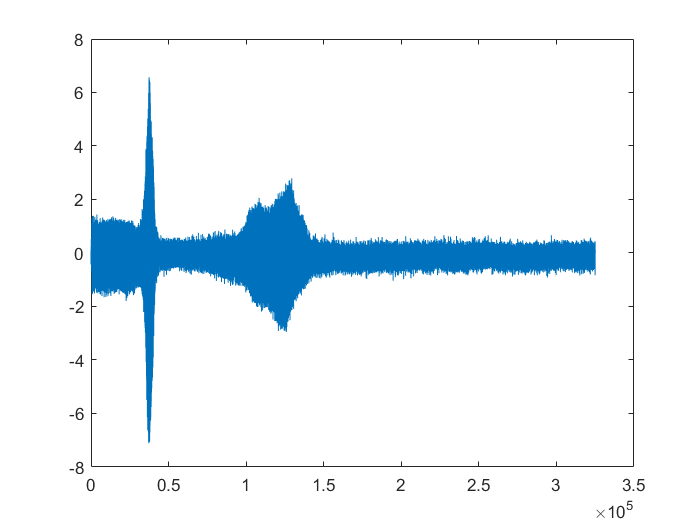

clear
load("files/switchingAFCMulti.mat");
y = data.y(1:end);
plot(y)

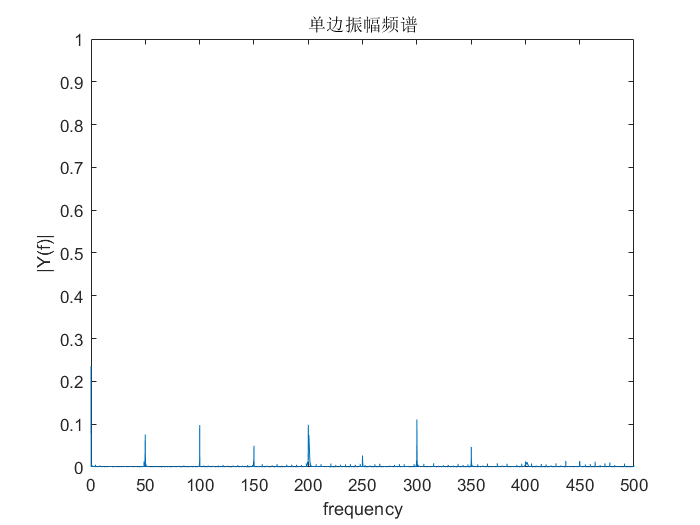


Fs = 5000;

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

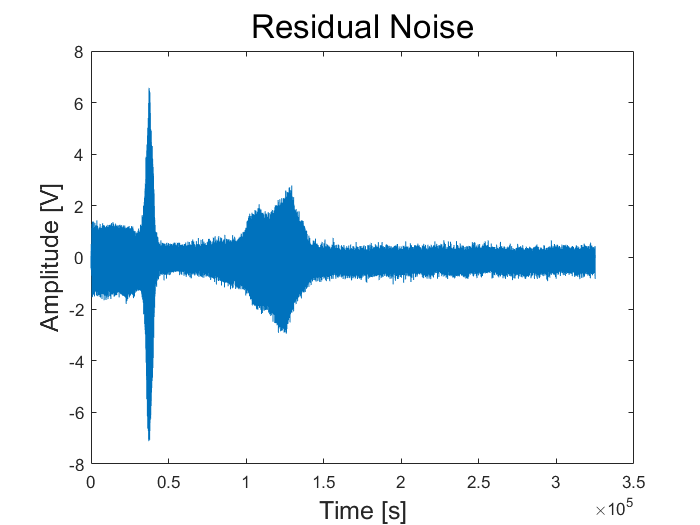

% clear
load("files/bandpass.mat")
load("files/switchingAFCMulti.mat");
y = data.y(1:end);
plot(y)

title("Residual Noise", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);

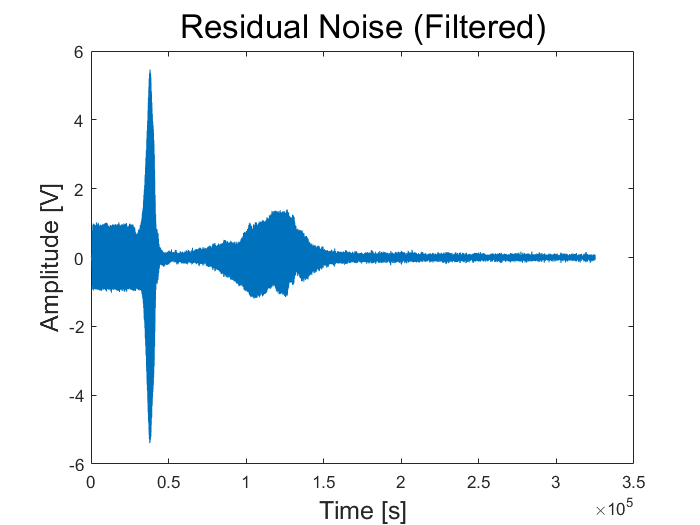


res = filter(bandpass50,y) + filter(bandpass100,y) + filter(bandpass150,y) + filter(bandpass200,y);
plot(res)

title("Residual Noise (Filtered)", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);

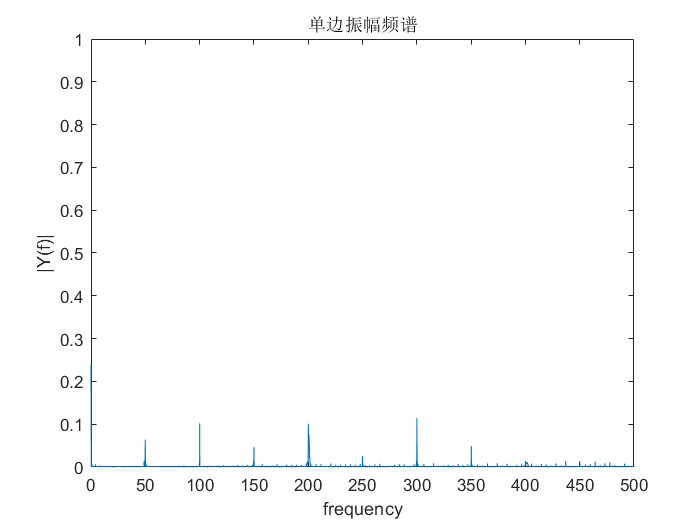


Fs = 5000;

y = data.y(10000:end);

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

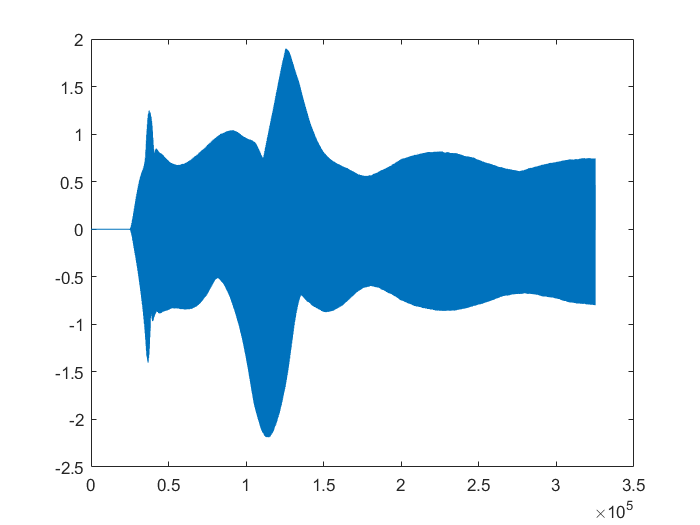




u = data.u(1:end);
plot(u)

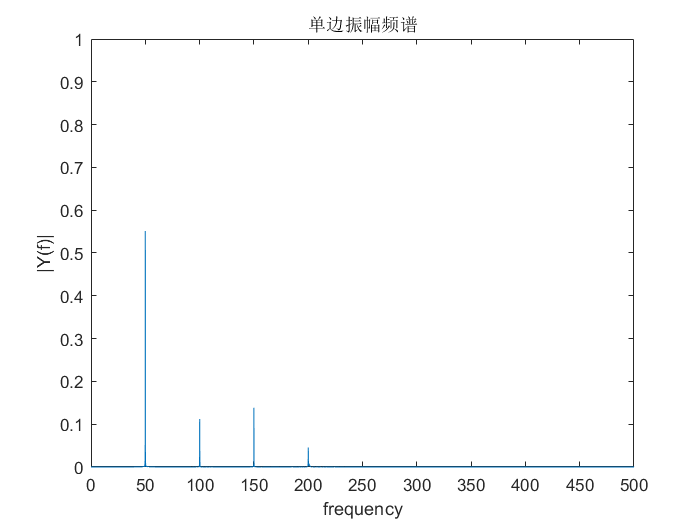

Fs = 5000;

[f, p] = fftFunc(Fs, length(u), u);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

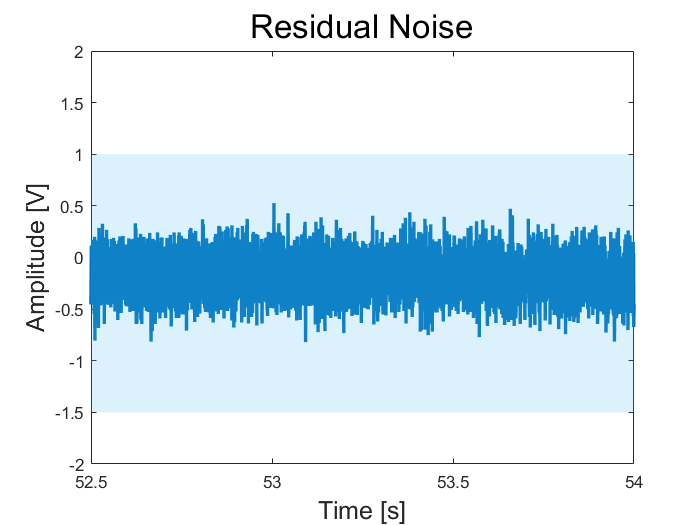

     1



    51



   101



   151



   201



   251



   301



   351



   401



   451



   501



   551



   601



   651




fig = figure;
N = 700;
im = cell(1, 120);
x = (1:length(y))/Fs;
plot(x, y, 'LineWidth', 2);

p = patch('vertices', [0, -1.5; 0, 1.0; 100, 1.0; 100 -1.5], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');
title("Residual Noise", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);
for i = 1:N
    ts = i*0.075;
    ylim([-2, 2])
    xlim([ts, ts+1.5]);
%     pause(0.075);
    % 注释下面两句话可以看到动态输出
        frame = getframe(fig);
        im{i} = frame2im(frame);
    if mod(i, 50) == 1
        disp(i)
    end
end

% % 下面是保存成 gif
filename = 'y_real.gif';
for idx = 1:N
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.075);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.075);
    end
    if mod(idx, 50) == 1
        disp(idx)
    end
end

     1

    51

   101

   151

   201

   251

   301

   351

   401

   451

   501

   551

   601

   651



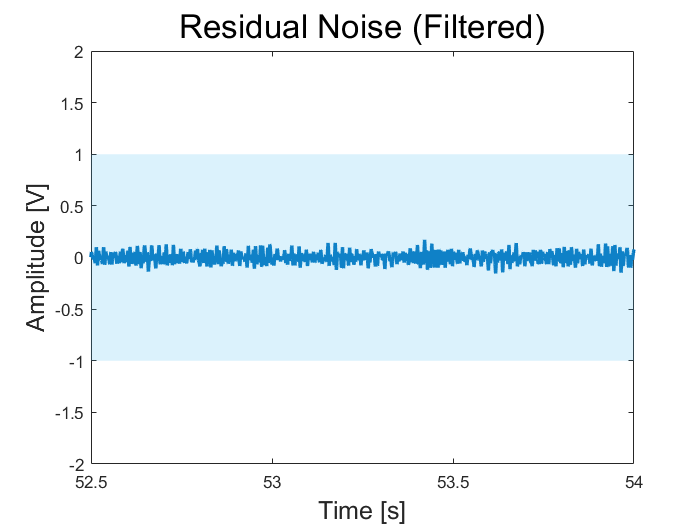

     1



    51



   101



   151



   201



   251



   301



   351



   401



   451



   501



   551



   601



   651




fig = figure;
im = cell(1, 120);
x = (1:length(y))/Fs;
yf = filter(bandpass50,y) + filter(bandpass100,y) + filter(bandpass150,y) + filter(bandpass200,y);
plot(x, yf, 'LineWidth', 2);

p = patch('vertices', [0, -1.0; 0, 1.0; 100, 1.0; 100 -1.0], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');
title("Residual Noise (Filtered)", "FontSize", 20);
ylabel("Amplitude [V]","FontSize", 15);
xlabel("Time [s]","FontSize", 15);

for i = 1:N
    ts = i*0.075;
    ylim([-2, 2])
    xlim([ts, ts+1.5]);
%     pause(0.075);
    % 注释下面两句话可以看到动态输出
        frame = getframe(fig);
        im{i} = frame2im(frame);
    if mod(i, 50) == 1
        disp(i)
    end
end

% % 下面是保存成 gif
filename = 'y_filtered.gif';
for idx = 1:N
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.075);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.075);
    end
    if mod(idx, 50) == 1
        disp(idx)
    end
end

     1

    51

   101

   151

   201

   251

   301

   351

   401

   451

   501

   551

   601

   651



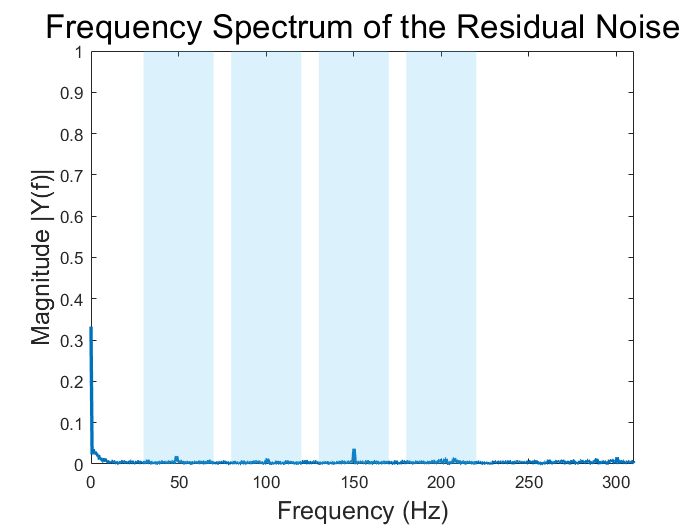

     1



    51



   101



   151



   201



   251



   301



   351



   401



   451



   501



   551



   601



   651




fig = figure;
im = cell(1, 120);

for i = 1:N

yn = y((i*Fs*0.075):(i*Fs*0.075+1.5*Fs));
[f, p] = fftFunc(Fs, length(yn), yn);

plot(f, p, 'LineWidth', 2)
xlim([0, 310])
ylim([0, 1])
title("Frequency Spectrum of the Residual Noise", "FontSize", 20);
ylabel("Magnitude |Y(f)|","FontSize", 15);
xlabel("Frequency (Hz)","FontSize", 15);

p1 = patch('vertices', [30, 0.0; 30, 1.0; 70, 1.0; 70 0.0], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');
p2 = patch('vertices', [80, 0.0; 80, 1.0; 120, 1.0; 120 0.0], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');
p3 = patch('vertices', [130, 0.0; 130, 1.0; 170, 1.0; 170 0.0], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');
p4 = patch('vertices', [180, 0.0; 180, 1.0; 220, 1.0; 220 0.0], ...
          'faces', [1, 2, 3, 4], ...
          'FaceColor', '#4DBEEE', ...
          'FaceAlpha', 0.2, ...
          'EdgeColor', 'None');

% pause(0.075);
%     % 注释下面两句话可以看到动态输出
        frame = getframe(fig);
        im{i} = frame2im(frame);
        if mod(i, 50) == 1
            disp(i)
        end
end

% 下面是保存成 gif
filename = 'y_fft.gif';
for idx = 1:N
    % 制作gif文件，图像必须是index索引图像
    [A, map] = rgb2ind(im{idx}, 256);
    if idx == 1
        imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.075);
    else
        imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.075);
    end
    if mod(idx, 50) == 1
        disp(idx)
    end
end

     1

    51

   101

   151

   201

   251

   301

   351

   401

   451

   501

   551

   601

   651



function [f, p] = fftFunc(Fs, L, y)
T= 1/Fs; %采样时间
t = (0:L-1)*T; %时间向量
NFFT = 2^nextpow2(L);
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);
p = 2*abs(Y(1:NFFT/2));
end